## MPC Realistic Deterministic Simulation 

clear all, clc, close all;

## Read MPC policy

fid = fopen('../MPC/data/deterministic/results0.json');
raw = fread(fid); 
str = char(raw'); 
fclose(fid); 
val = jsondecode(str);

aTc = val.states.v1;
IPTG = val.states.v2;

sbioloadproject Genetic_Toggle_Switch.sbproj

### Adds events for input variation

for i = 1:length(IPTG)
    trigger = strcat('time >= ', int2str((i-1)));
    evnt_IPTG = strcat('IPTG = ', num2str(IPTG(i)), '*u0');
    evnt_aTc = strcat('aTc = ', num2str(aTc(i)), '*u0');
    addevent(m1, trigger, {evnt_aTc, evnt_IPTG});
end

### Simulation

sim = sbiosimulate(m1);

### Average trajectory

avg_time = (0:1:1200);
LacI = sim.Data(:,3);
TetR = sim.Data(:,5);

[avg_LacI, avg_TetR] = compute_average_trajectory(LacI, TetR, avg_time);

LacI_ref = 750;
TetR_ref = 300;

### Simulation results

close all;
figure(1);
clf reset
plotbrowser('on');

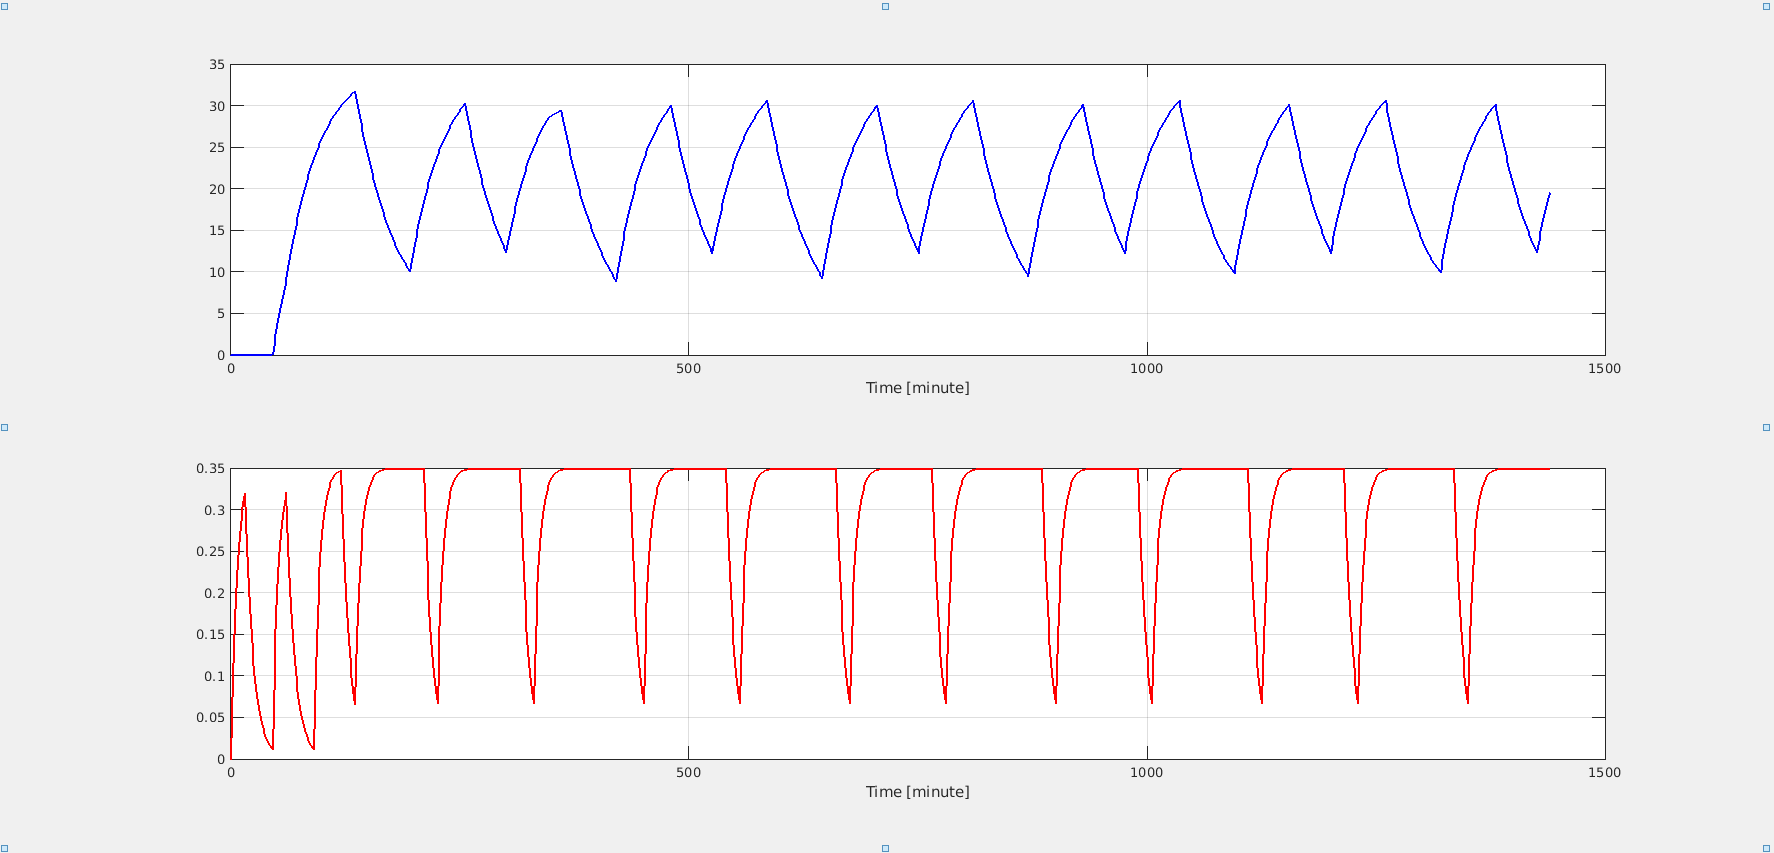

title('Inputs');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,6), 'DisplayName','aTc');
set(pl,'linewidth',2, 'Color', 'b');
xlabel('Time [minute]');
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,1), 'DisplayName','IPTG');
set(pl,'linewidth',2, 'Color', 'r');
xlabel('Time [minute]');
grid

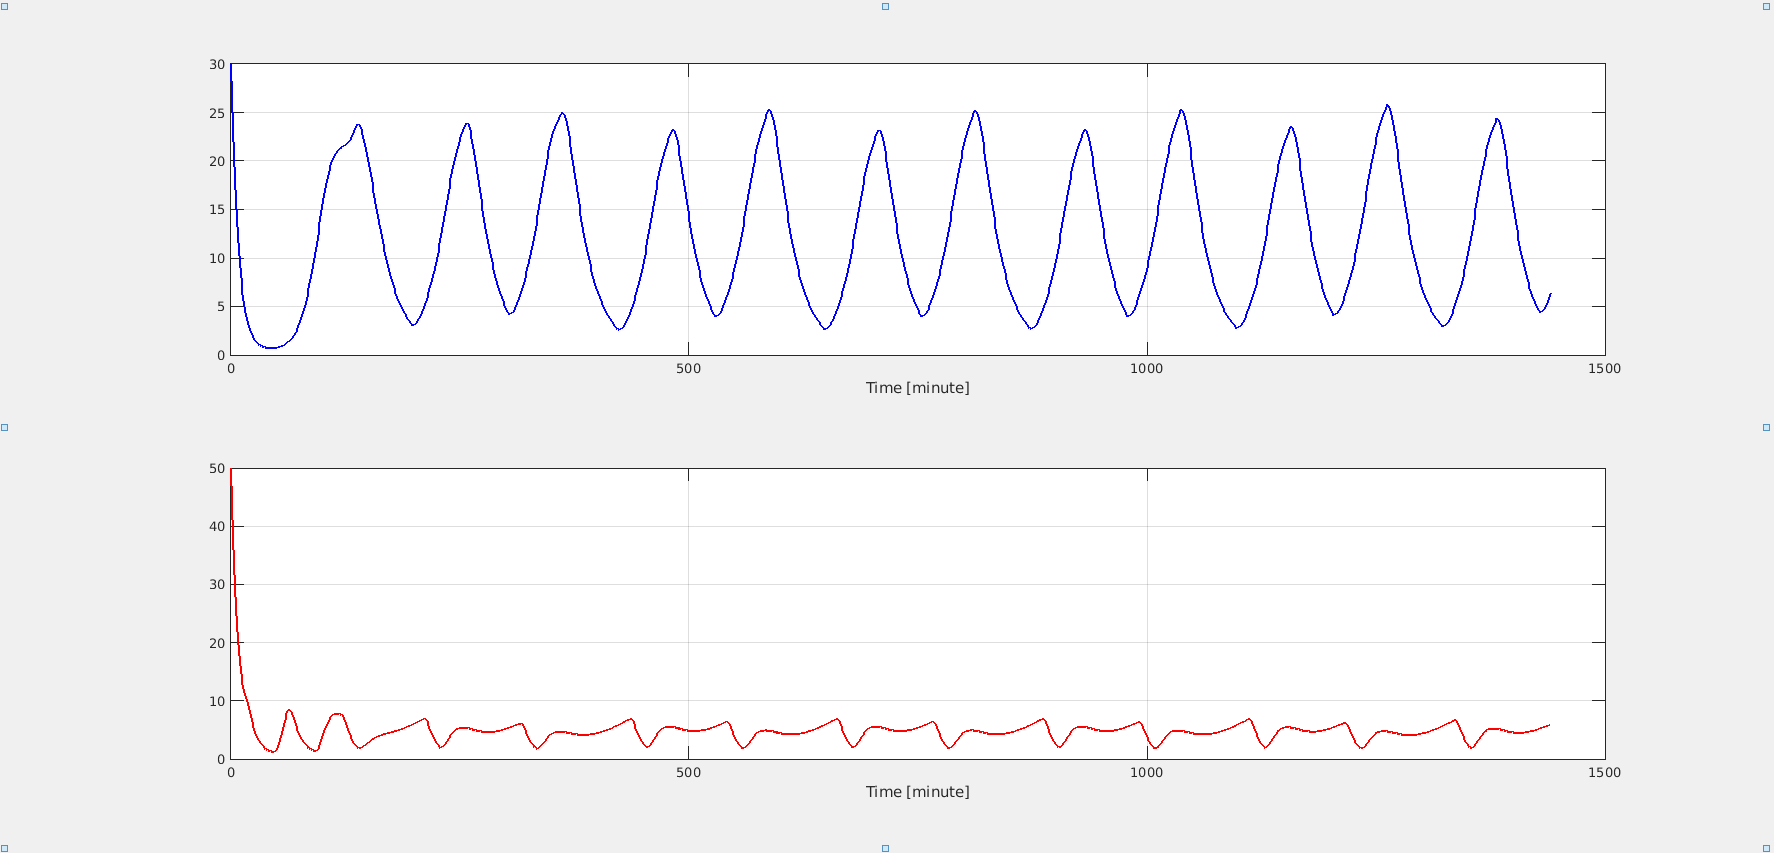

figure(2);
clf reset
plotbrowser('on');
title('mRNAs');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,2), 'DisplayName','mRNA LacI');
set(pl,'linewidth',2, 'Color', 'b');
xlabel('Time [minute]');
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,4), 'DisplayName','mRNA_TetR');
set(pl,'linewidth',2, 'Color', 'r');
xlabel('Time [minute]');
grid

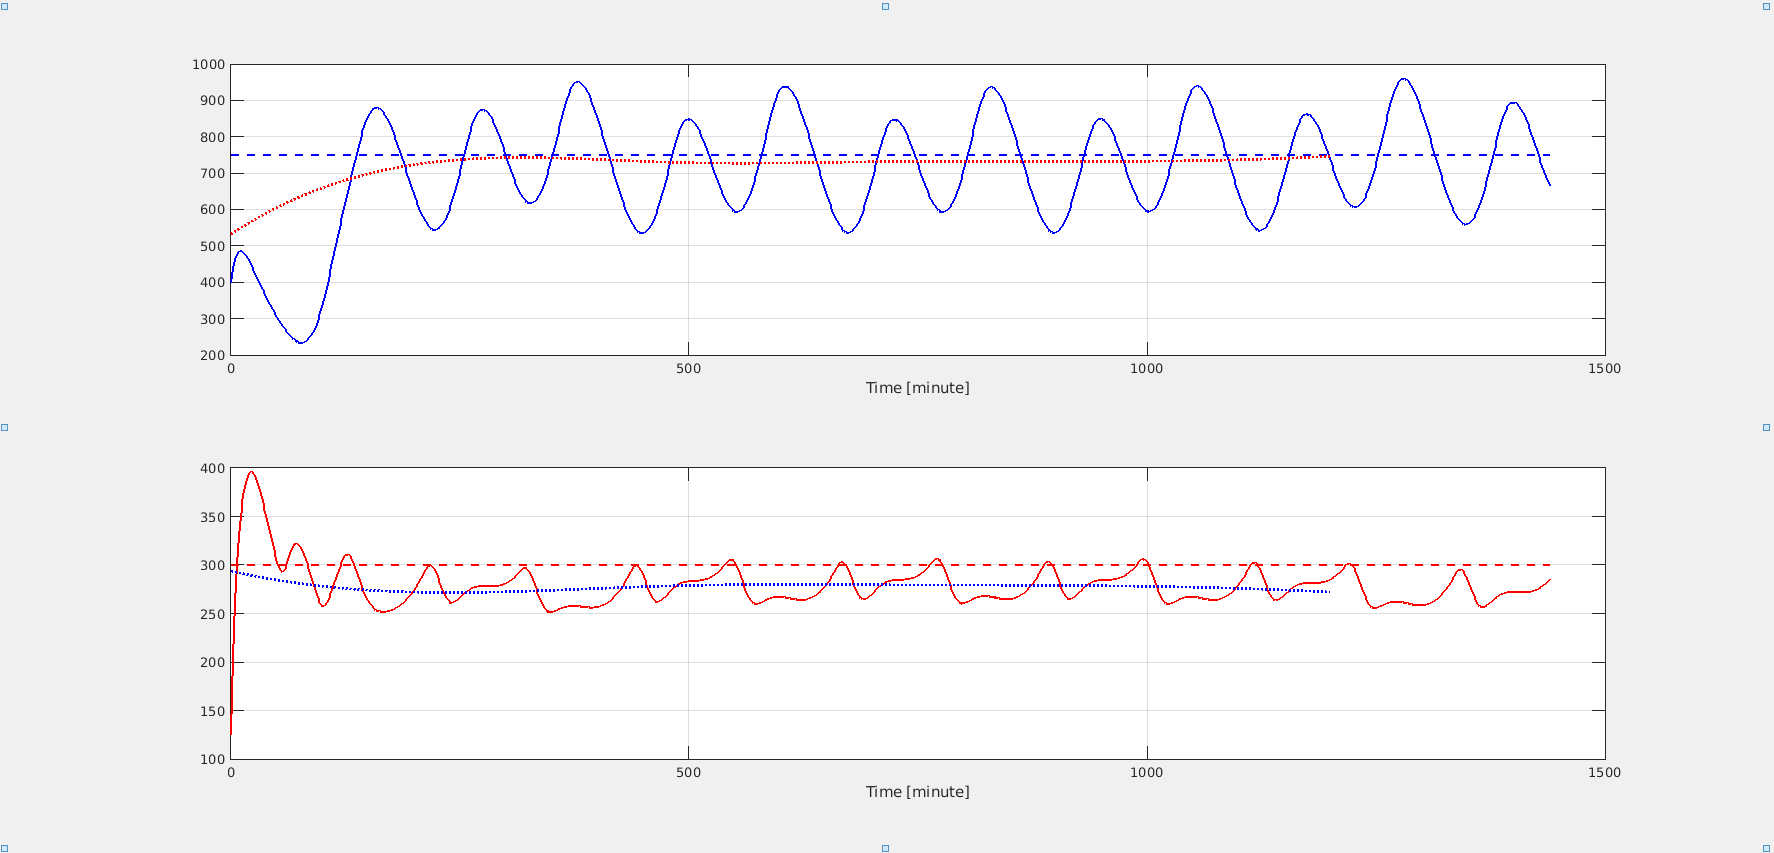

figure(3);
clf reset
plotbrowser('on');
title('Proteins');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,3), 'DisplayName','LacI');
set(pl,'linewidth',2, 'Color', 'b');
hold on
pl = plot(sim.Time, LacI_ref*ones(1, length(sim.Time)), 'DisplayName','TetR Reference');
set(pl,'linewidth',2, 'Color', 'b', 'LineStyle', '--');
pl = plot(avg_time, avg_LacI, 'DisplayName','Average LacI');
set(pl,'linewidth',2, 'Color', 'r', 'LineStyle', ':');
xlabel('Time [minute]');
hold off
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,5), 'DisplayName','TetR');
set(pl,'linewidth',2, 'Color', 'r');
hold on
pl = plot(sim.Time, TetR_ref*ones(1, length(sim.Time)), 'DisplayName','TetR Reference');
set(pl,'linewidth',2, 'Color', 'r', 'LineStyle', '--');
pl = plot(avg_time, avg_TetR, 'DisplayName','Average TetR');
set(pl,'linewidth',2, 'Color', 'b', 'LineStyle', ':');
xlabel('Time [minute]');
hold off
grid

### Performance metrics

[ISE,ITAE] = compute_performance_metrics(avg_LacI, avg_TetR, LacI_ref, TetR_ref)

ISE = 12.2279

ITAE = 5.7879e+04